# ECE 486 S23 Project Section 5

### @author Laurent Zheng (20818351)

## 1. Adding Dynamic Parameters

From the design outlined in previous sections, we can see that we have a total of 3 links. However, since the joint dimensions were also being considered, the last rotary joint connecting to the paddle would also have to be considered as a link.

To assign masses to each link, we can first de that $L_1$ as the link connecting the base(assuming the first prismatic joint is at the base) of the robot to the first rotary joint with a length of 0.3m; $L_2$ as the link connecting the first rotary joint to the second prismatic joint; $L_3$ as the joint connecting second prismatic joint to the second rotary joint; and $L_4$ connecting the second rotary joint to the paddle (shown as the raidus portion of the second rotary joint).

Note that the deisng image doesn't match the assignment of joint and link behavior exactly. However, to simplify calculcations while making assumptions that the joints are dimensionless, the links are 10kg/m cylinders, etc, the following calculaiton on masses and inertia will follow the assignment as described above.

$L_1$ has a length of 0.3m,  we have a mass of 3kg, where the centre of mass is in the middle of the cylinder. In refrence of the base frame, we have:


$$M_{01} \pmatrix{\mathbb{I} & 0.15\hat{z} \cr 0 & 1}$$


$L_2$ has a length of 0.55m, starting from the first rotary joint and ending at the middle of the 2 rotary joint. Here, we have a mass of 5.5 kg. We can then write:


$$R_{12} = 
\pmatrix{0 & 0 & -1 \cr 0 & 1 & 0 \cr 1 & 0 & 0}
$$
 

as the rotation from the $L_1$ centre frame to the $L_2$ centre frame. And thus,


$$M_{12} = \pmatrix{R_{12} & [0.275,0,0.15]^T \cr 0 & 1}$$


$L_3$ has a length of 1.55m and a mass of 15.5 kg. In the robot's zero position. This is comes from the fact that at the zero poisition, in only sticks out of the second prismatic joint by 0.55m and has the capability to extending 1m outwards. This in means in the fixed reference frame {s}, the centre of mass is at $[-0.925,0, -0.2]^T$. And with respect to the previous link, we have


$$M_{23} = \pmatrix{\mathbb{I} & -0.3\hat{z] \cr 0 & 1}$$


$L_4$ has  a length of 0.02m and a mass of 0.2 kg. This link is merely to represent the rotary joint's raidus as the original design had dimensions for the joints. Again, with respect to the previous link, we can write


$$M_{34} = \pmatrix{\mathbb{I} & 0.755\hat{z] \cr 0 & 1}$$


We can also note that all of the links are cylindrical with a radius of 1. The following shows a side view image of each joint at the zero position from the side:

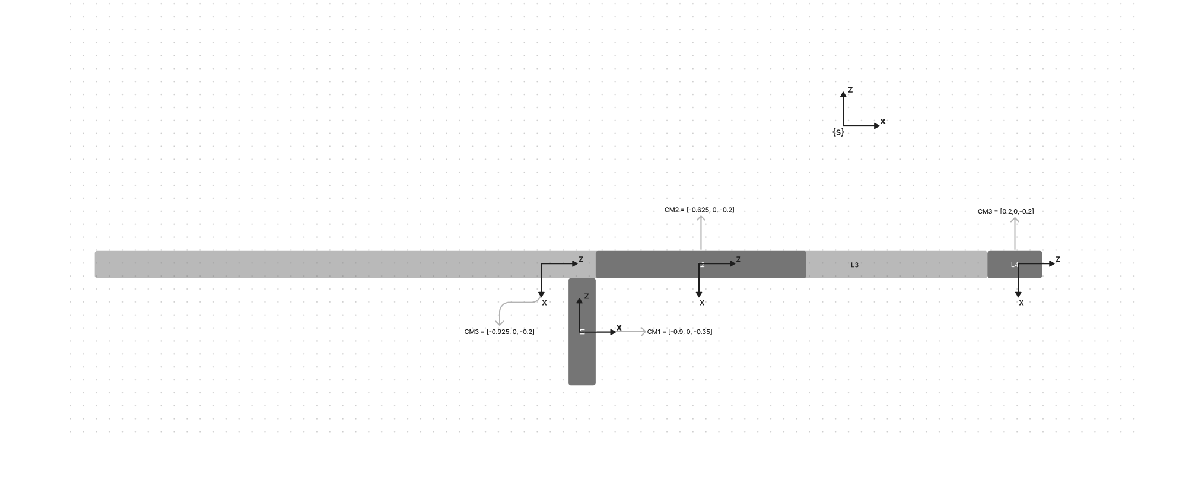

imshow(imread("linkcm.png"))

We can also assume that all of the acutators are at the end of each link. In this case, the first prismatic actuator is at the base. The first rotary actuator is on top of the first link. The first primatic actuator is on the right of the second link. And the last rotary actuator is at the right of the third link. This is also shown in the following image where the** purple** circles locates the acutators:

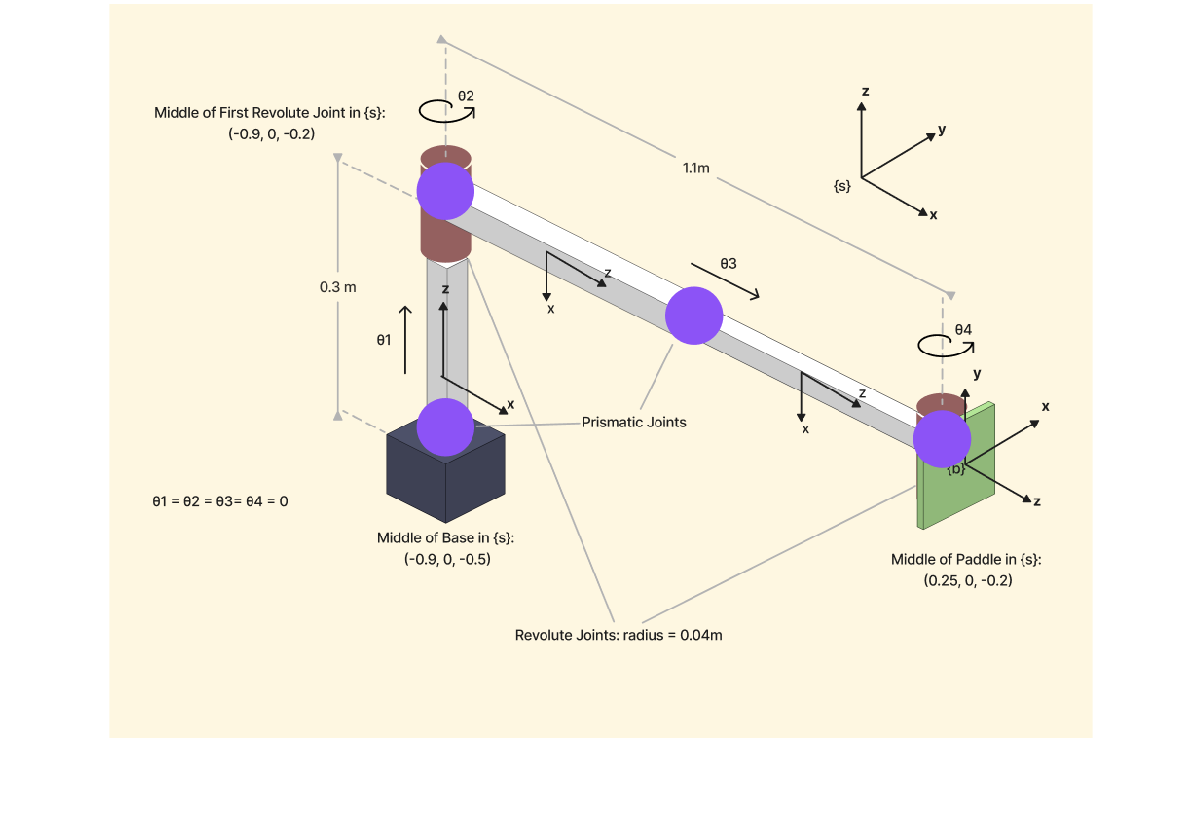

imshow(imread("actuator_outline.png"))

To calculate the inertia of each joints(again assuming that the links are cylindrical and not prismatic in the original design), we can say that:

$I = diag(I_{xx}, I_{yy}, I_{zz})$ that follows a cyclinder where  $I_{xx} = m(3r^2+h^2)/12$, $I_{yy} = m(3r^2+h^2)/12$, $I_{zz} = mr^2/2$. Assuming a radius of 1 for all cylinders. We can then write the inertial matrices as 


$$I_i = R_{i-1, i}^T I_{s,i}R_{i-1,1}$$


Where the rotation from frame to frame is outlined in the mass matrices above and the each inerita matrices follows the same calculation in the fixed frame.

Adding onto that the for the actuators, we can say use the parrallel axis therom to say that 


$$I_d = I_{cm} + md^2$$


where each actuator is d distance away from the centre of mass of the link attached to it in the princinple aixs. This is the same for all actuators in our case.

## 2. Dynamics Code + Discussion


% Constants:
% T_sh - home pose of the paddle (relative to the fixed frame)
% g - acceleration due to gravity (relative to the fixed frame)
R_sh = [0 1 0; 0 0 1; 1 0 0]';
p_sh = [0.25 0 0.25]';
T_sh = RpToTrans(R_sh, p_sh);
g = [0; 0; -9.8];

% Robot Design (copied from Section 3: Design or your revised design)
% Define joint_types, joint_limits, B_list, S_list, and M
joint_types = ['P','R','P','R'];
joint_limits = [[0;1],[-pi;pi],[0;1],[-pi/2;pi/2]];
S_list = [[0;0;0;0;0;1],[0;0;1;0;0.9;0]  ,[0;0;0;1;0;0],[0;0;1;0;-0.2;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
B_list = [[0;0;0;0;1;0],[0;1;0;1.15;0;0],[0;0;0;0;0;1],[0;1;0;0.05;0;0]]; % must have the dimensions [6, n_joints] and each column must be a screw axis
M = [0 0 1 0.25; 1 0 0 0; 0 1 0 -0.2; 0 0 0 1]; % must be in SE(3)
speed_limits(joint_types == 'P') = 0.5;
speed_limits(joint_types == 'R') = 2;
n_joints = length(joint_types);

% Robot Dynamic Parameters
% Define M_list and G_list
R01 = eye(3);
p01 = [0 0 0.15]';
M01 = RpToTrans(R01, p01);

R12 = [0 0 -1;
       0 1 0;
       1 0 0];
p12 = [0.275 0 0.15]';
M12 = RpToTrans(R12, p12);

R23 = eye(3);
p23 = [0 0 0.55]';
M23 = RpToTrans(R23, p23);

R34 = eye(3);
p34 = [0 0 0.295]';
M34 = RpToTrans(R34, p34);

M_list = cat(3, M01, M12, M23, M34, T_sh); % concatenates the matrices into a list of n+1 matrices



m1 = 3;
r1 = 1;
h1 = 0.3;
I1 = [m1 * (3*r1.^2 + h1.^2)/12, 0, 0;
      0, m1 * (3*r1.^2 + h1.^2)/12, 0;
      0, 0, m1 * r1.^2 / 2];
G1 = [I1, zeros(3);
     zeros(3), m1 * eye(3)];
% must be a 6x6 matrix with a 3x3 rotational inertia in the top left corner and mass*eye(3) in the bottom right corner



m2 = 5.5;
r2 = 1;
h2 = 0.55;
I2 = [m2 * (3*r2.^2 + h2.^2)/12, 0, 0;
      0, m2 * (3*r2.^2 + h2.^2)/12, 0;
      0, 0, m2 * r2.^2 / 2];
R02 = R01 * R12;

G2 = [R02.' * I2 * R02, zeros(3);
     zeros(3), m2 * eye(3)];


m3 = 5.5;
r3 = 1;
h3 = 0.55;
I3 = [m3 * (3*r3.^2 + h3.^2)/12, 0, 0;
      0, m3 * (3*r3.^2 + h3.^2)/12, 0;
      0, 0, m3 * r3.^2 / 2];
R03 = R02 * R23;

G3 = [R03.' * I3 * R03, zeros(3);
     zeros(3), m3 * eye(3)];

m4 = 0.4;
r4 = 1;
h4 = 0.04;
I4 = [m4 * (3*r4.^2 + h4.^2)/12, 0, 0;
      0, m4 * (3*r4.^2 + h4.^2)/12, 0;
      0, 0, m4 * r4.^2 / 2];
R04 = R03 * R34;

G4 = [R04.' * I4 * R04, zeros(3);
     zeros(3), m4 * eye(3)];


G_list = cat(3, G1, G2, G3, G4); % concatenates the matrices into a list of n matrices

centre = [0.7, 0, 0.3]';

thetades = generate_trajectory(centre, 2, 5)

home_configs =     0.4500         0         0         0


thetades =     0.4500         0         0         0
    0.4514         0    0.0123         0
    0.4552         0    0.0458         0
    0.4608         0    0.0950         0
    0.4676         0    0.1549         0
    0.4750         0    0.2200         0
    0.4824         0    0.2851         0
    0.4892         0    0.3450         0
    0.4948         0    0.3942         0
    0.4986         0    0.4277         0


n_samples = size(thetades,1);
Ftipdes = zeros(n_samples, 6) % should always have 0 force on tip

Ftipdes =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0



dthetades = [zeros(1,4);diff(thetades)*5] % joint velocities

dthetades =          0         0         0         0
    0.0070         0    0.0616         0
    0.0190         0    0.1672         0
    0.0280         0    0.2464         0
    0.0340         0    0.2992         0
    0.0370         0    0.3256         0
    0.0370         0    0.3256         0
    0.0340         0    0.2992         0
    0.0280         0    0.2464         0
    0.0190         0    0.1672         0


ddthetades = [zeros(1,4);diff(dthetades)*5] % joint accelerations

ddthetades =          0         0         0         0
    0.0350         0    0.3080         0
    0.0600         0    0.5280         0
    0.0450         0    0.3960         0
    0.0300         0    0.2640         0
    0.0150         0    0.1320         0
    0.0000         0    0.0000         0
   -0.0150         0   -0.1320         0
   -0.0300         0   -0.2640         0
   -0.0450         0   -0.3960         0


% Use the forward dynamics function to make sure that the robot moves due to gravity when starting at the home position
taudes = InverseDynamicsTrajectory(thetades, dthetades, ddthetades, [0,0,-9.8]', Ftipdes, M_list, G_list, S_list)

taudes =   141.1200         0         0         0
  141.6240         0    1.8172         0
  141.9840         0    3.1152         0
  141.7680         0    2.3364         0
  141.5520         0    1.5576         0
  141.3360         0    0.7788         0
  141.1200         0    0.0000         0
  140.9040         0   -0.7788         0
  140.6880         0   -1.5576         0
  140.4720         0   -2.3364         0


Plotting the joint torque for a trajectory for the paddle to come to the centre of the cuboid, we can see in the following that joints 2 and 4 are not expierencing torque as the movement are penpendicular to its direction of freedom. We also see that the torque ramps up and back down proportional to the derivative of the of the velocity of the joints. This is because we used a cubic trajectory.

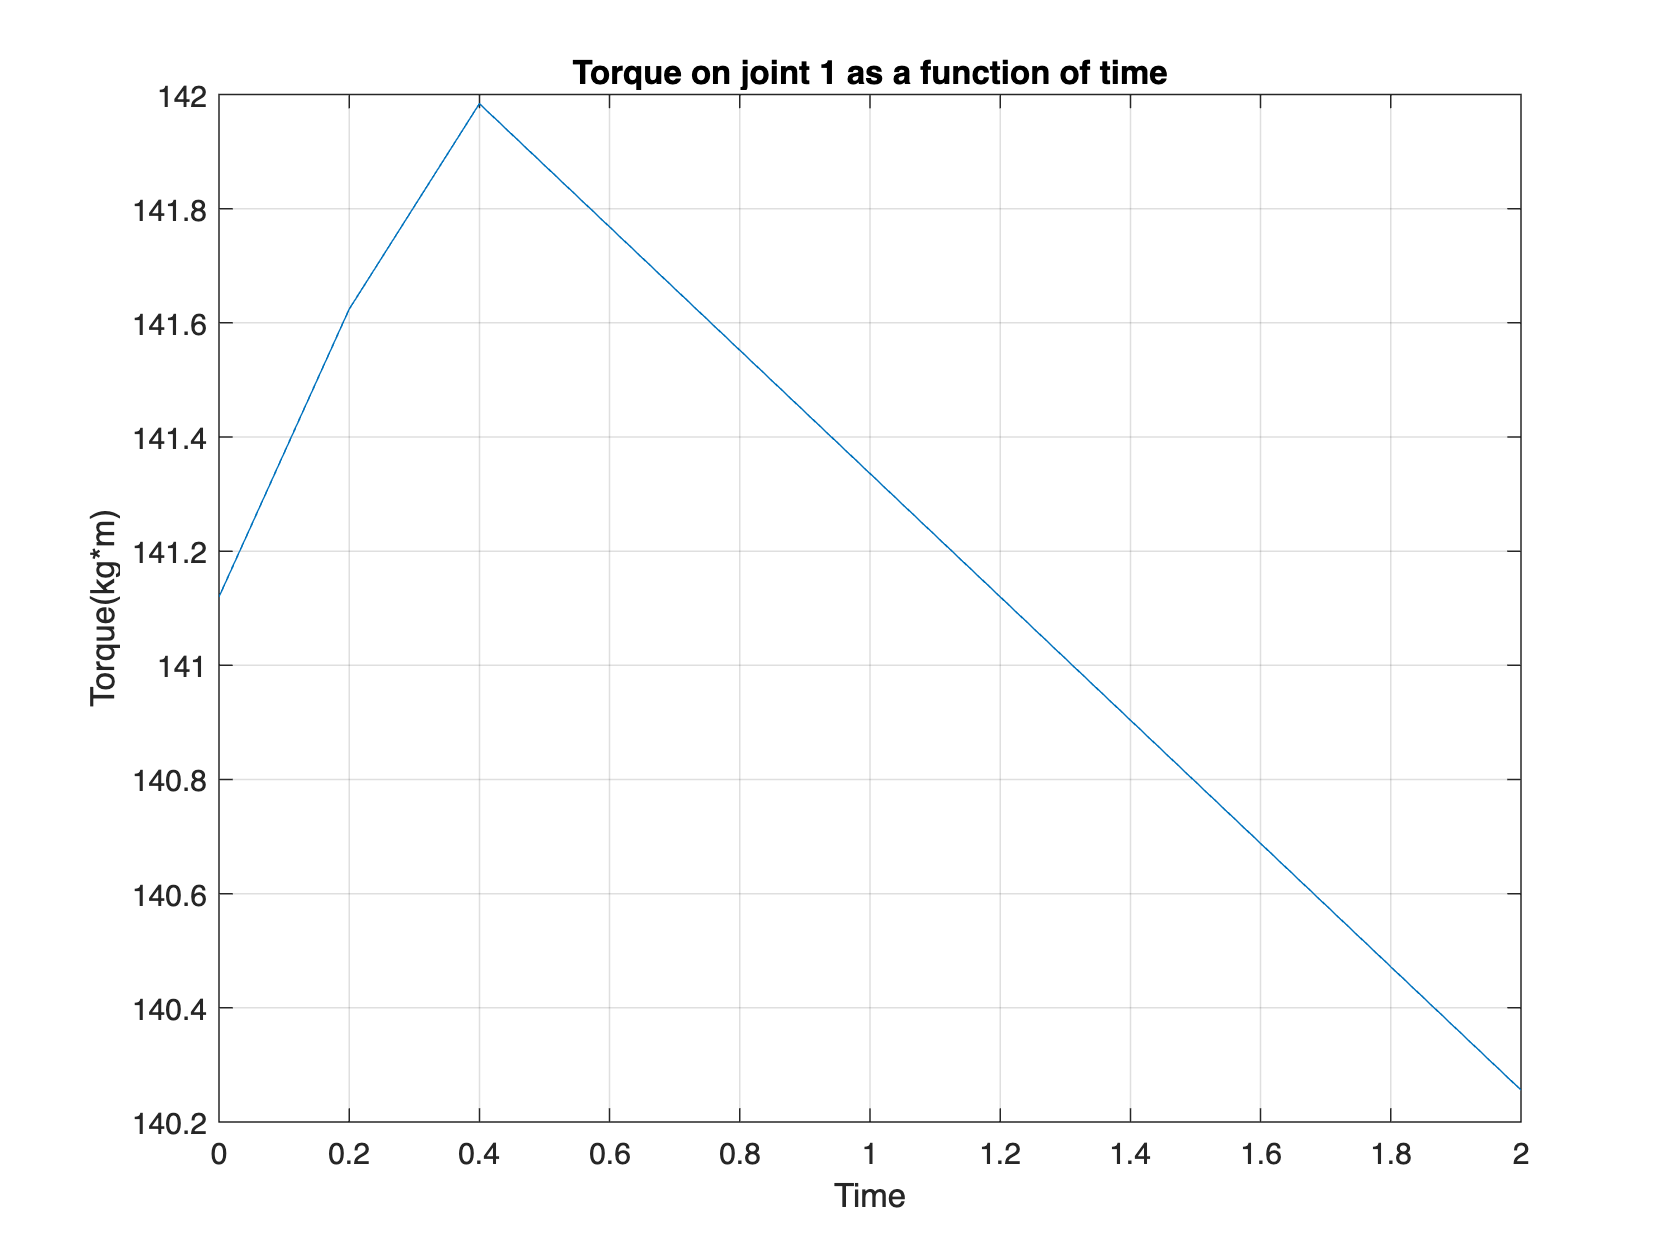

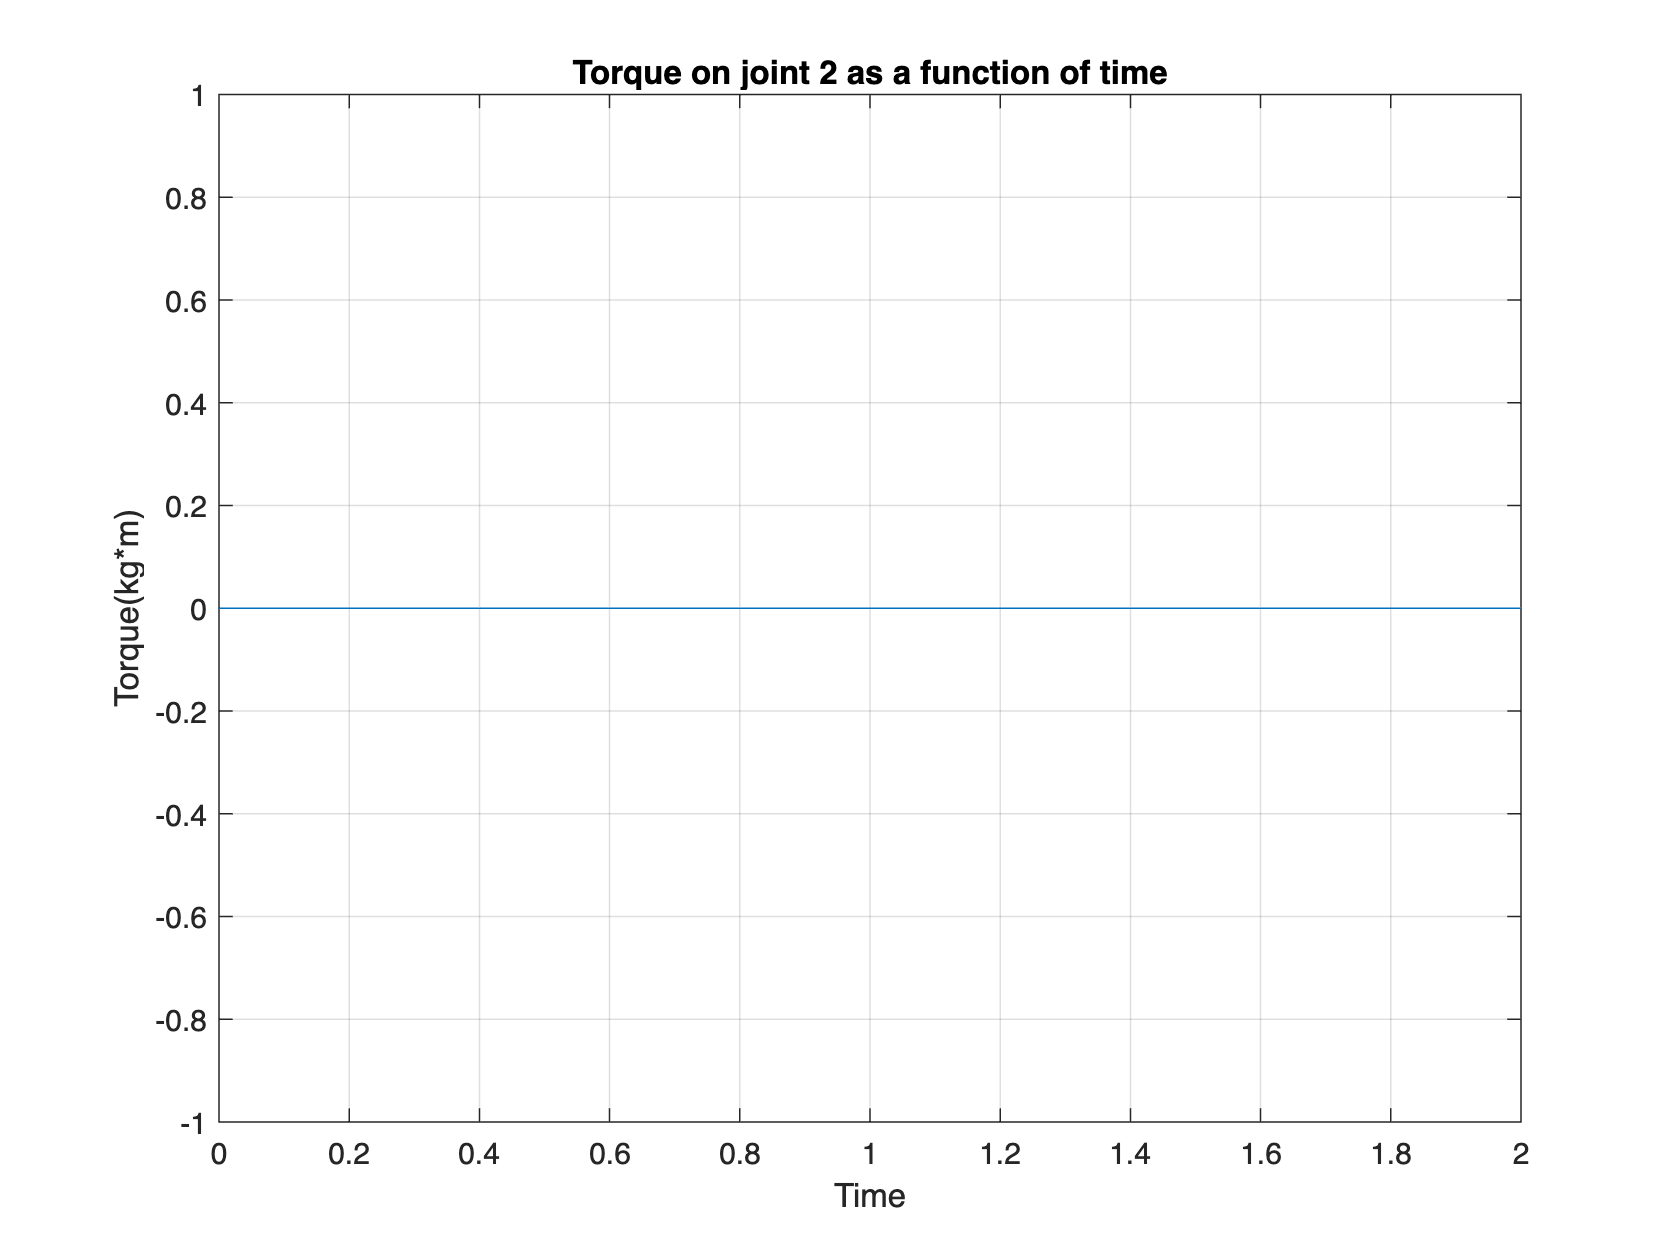

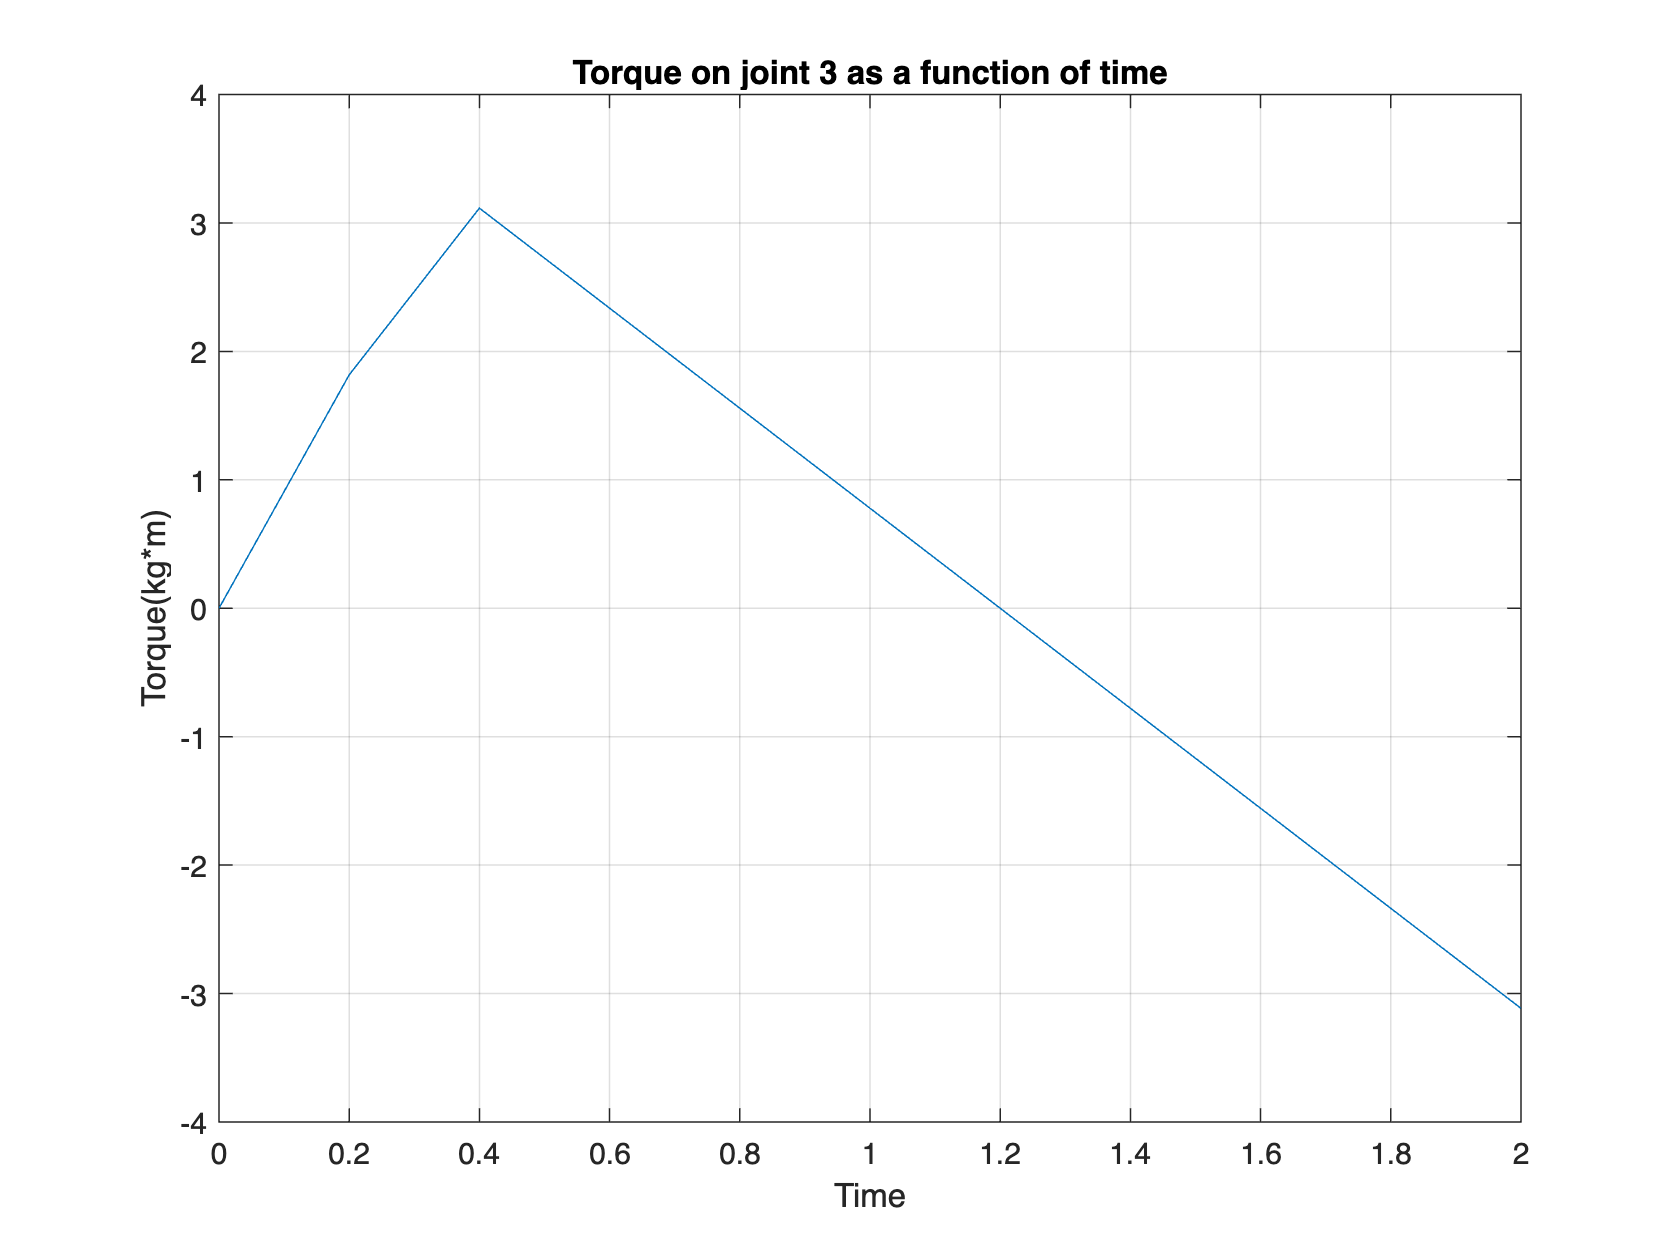

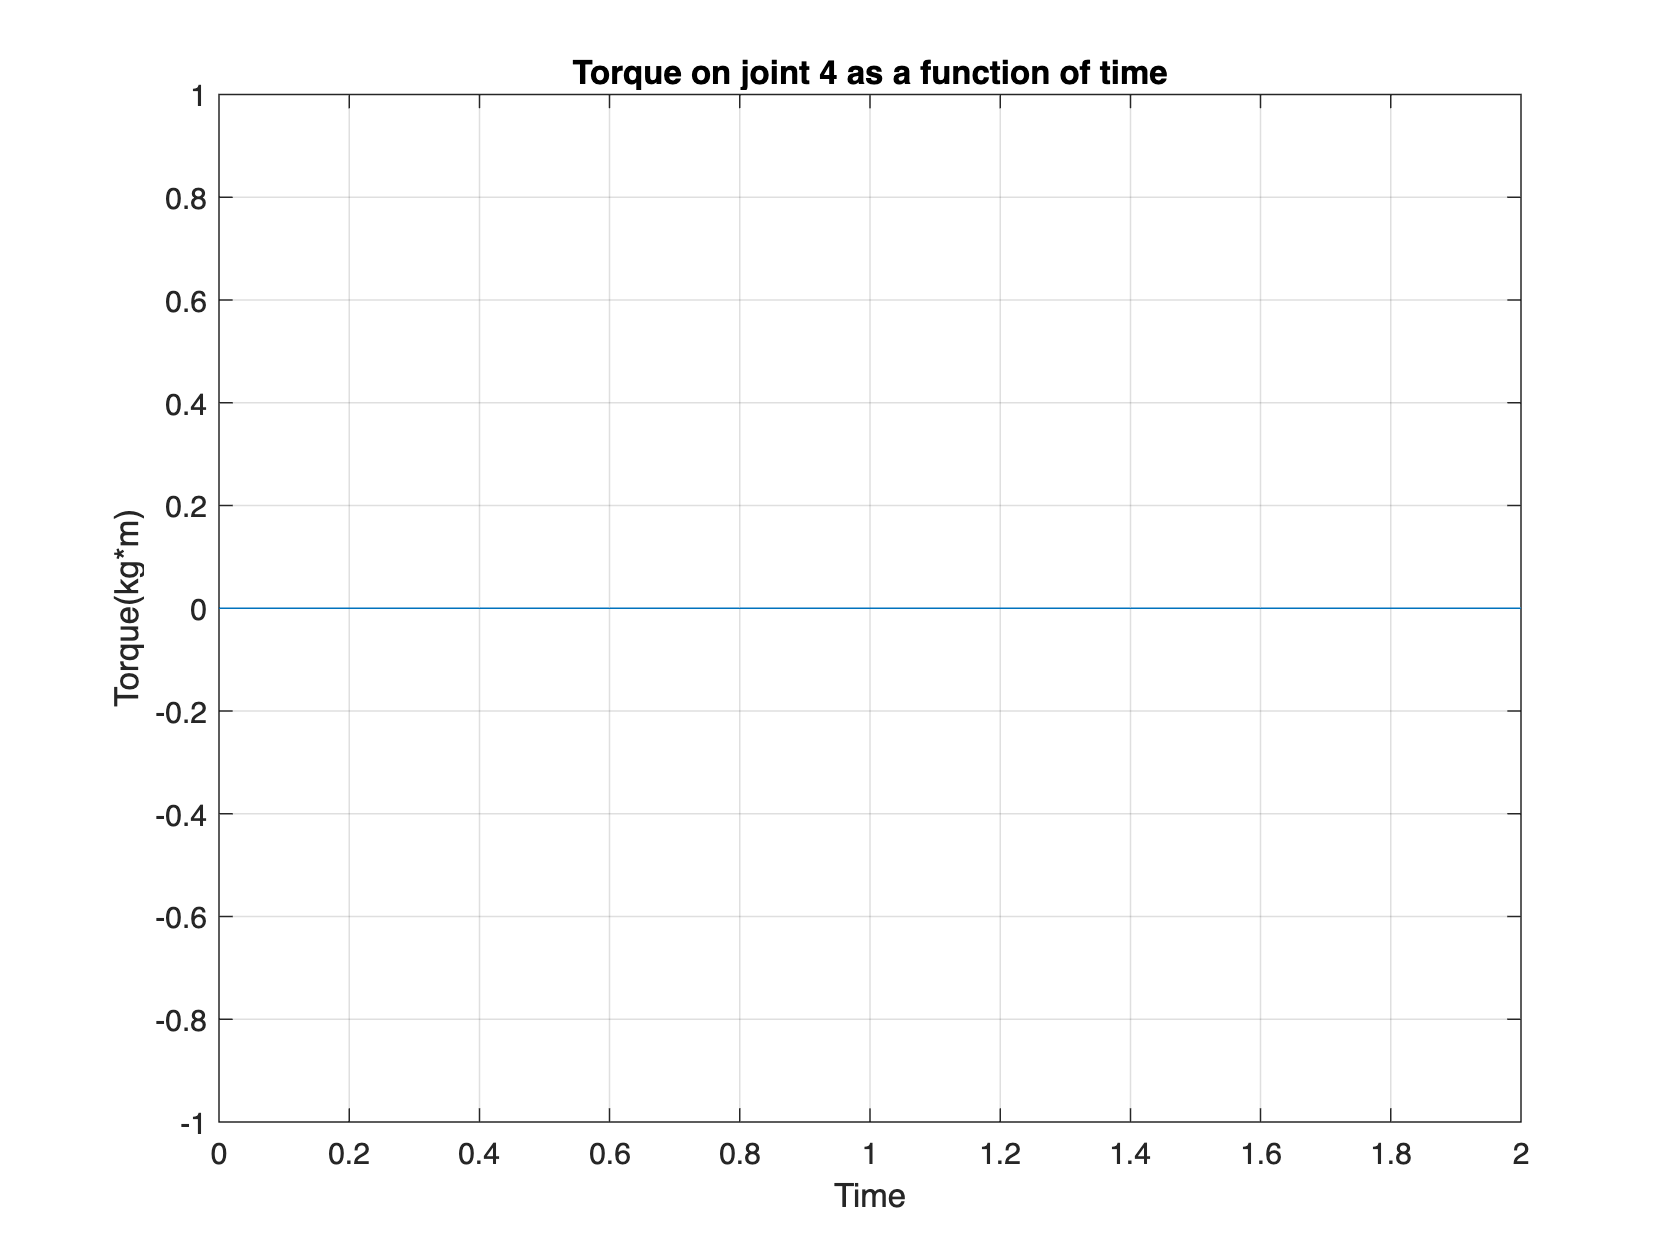

for col = 1:4
    figure; % Create a new figure for each plot
    plot(linspace(0, 2, n_samples), taudes(:, col));
    xlabel('Time');
    ylabel(sprintf('Torque(kg*m)', col));
    title(sprintf('Torque on joint %d as a function of time', col));
    grid on;
end

How the code could be used later:

We can use our defined G_list and M_list to feed into the inverse and forward dynamics equation as shown above. This means we get to see the outputs $\tau$ when working on the controller of the robot as the feedback control uses the computed torques to tune for the parameters of the controller. 

function [T_sc, solution_list] = inverse_kinematics(var)
if size(var)==[4 4] & TestIfSE3(var)
    % The input variable is in SE(3), so set T_sc to the input
    T_sc = var;
else
    % The input variable is not in SE(3), so set p_sb to the input
    p_sb = reshape(var,[3,1]);

    % Generate a desired contact pose T_sc given the ball position p_sb
    % Note: Copy this section from the IK problem in Section 4: Validation
    R_sh = [0 0 1; 1 0 0; 0 1 0];
    p_sh = [0.25; 0; 0.25];
    T_sh = RpToTrans(R_sh, p_sh);
    
    contact_angle = 0;
    p_hb = T_sh \ [p_sb; 1];
    p_hb = p_hb(1:end-1);
    
    R_hc = [cos(contact_angle) 0 sin(contact_angle); 0 1 0; -sin(contact_angle) 0 cos(contact_angle)];
    p_hc = p_hb - (R_hc * [0; 0; 0.01]);
    T_hc = RpToTrans(R_hc, p_hc);
    
    T_sc = T_sh * T_hc;

end

% Find all valid solutions of the IK problem for your robot to place the paddle in pose T_sc
% Note: Copy this section from the IK problem in Section 4: Validation
% Note: If T_sc is provided, it may be the home pose outside the cuboid

if size(var)==[4 4] & TestIfSE3(var)
    [~,p_sb] = TransToRp(var);
end

contact_angle = 0;
    
% calculation follows derivation above (Here we just merged delta into alpha)
alpha = p_sb(1) + 0.9 - cos(contact_angle)*0.06;
beta = p_sb(2) + sin(contact_angle)*0.06;
theta1 = 0.2 + p_sb(3);
theta2 = atan2(beta, alpha);
theta3 = sqrt(beta.^2 + alpha.^2) - 1.1;
theta4 = contact_angle - theta2;
sol = [theta1, theta2, theta3, theta4];
solution_list = [];

% check if ball is in cuboid before assigning solution: NOTE only one
% unique solution in our case.
if p_sb(1) >= 0.3 && p_sb(1) <= 1.1 && ...
   p_sb(2) >= -0.8 && p_sb(2) <= 0.8 && ...
   p_sb(3) >= -0.1 && p_sb(3) <= 0.7
    solution_list = [sol];
end

if p_sb == [0.25 0 0.25]'
    solution_list = [0.45,0,0,0];
end


end

% Inputs
% p_sb - The position of the ball at time tc (in the fixed frame)
% t_c - The time at which the ball will be at p_sb
% freq - The sampling frequency (in Hz) used to generate your trajectory
% Outputs
% joint_traj - A matrix defining a joint trajectory were each row is a set of joint positions. Empty matrix if no solution found.
function joint_traj = generate_trajectory(p_sb, t_c, freq)
    % Find all valid configurations which contact the ball at p_sb
    [~, goal_configs] = inverse_kinematics(p_sb);
    if isempty(goal_configs)
        joint_traj = [];
        return;
    end
    
    % Find all valid home configurations
    T_sh = RpToTrans([0 1 0; 0 0 1; 1 0 0]', [0.25 0 0.25]');
    [~, home_configs] = inverse_kinematics(T_sh);

% Find a valid trajectory for your robot to follow to end up with the paddle at rest in pose T_sc at or before t_c
display(home_configs)

home_configs = [0.45,0,0,0];

ts = 1/freq;
T = t_c;
t = 0:ts:T;
% 3rd order time saling trajectory
time_f = (3.*t.^2/T.^2 - 2.*t.^3/T.^3).';

joint_traj = home_configs + time_f*(goal_configs - home_configs);


end